# **PRACTICA 3: FILTROS **(import para examen)

Calculad las inversas de las transformadas Z y repres´entalas comparadas con los resultados de clase: 

X(z) = 1+0,3z1 10,7z1 

X(z) = 1+0,3z1 10,7z1+0,49z2 

X(z) = 10,48z1 11,6z1+0,64z2

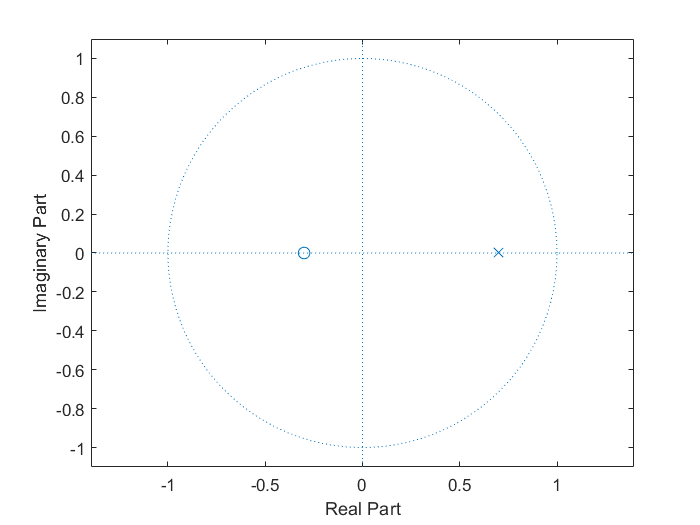

%X1=(1+0.3*z^(-1))/(1-0.7*z^(-1));
num=[1,0.3]; %creo un vector donde el primer miembro es el de mayor orden z^0 y el segundo el de menor z^(-1)
denom=[1,-0.7];
zplane(num,denom) %representacion de los zeros y los polos de la transformada, no me lo piden

[r,p,k]=residuez(num,denom) %filtro de manera mas sencilla: X(z)=(1.43/(1-0.7*z(-1)))-0.43

r = 1.4286

p = 0.7000

k = -0.4286

n=0:20 %por ejemplo

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


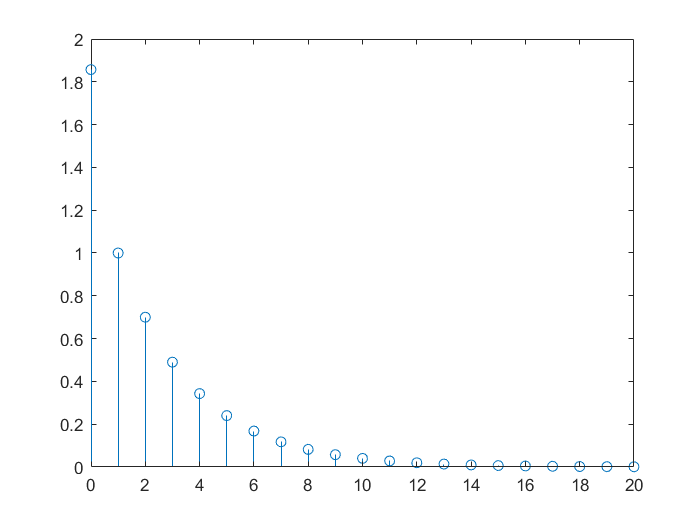

x=r(1)*(p(1).^n).*escalon(n,0)-k(1).*delta(n,0); %inversa de la transformada
stem(n,x)

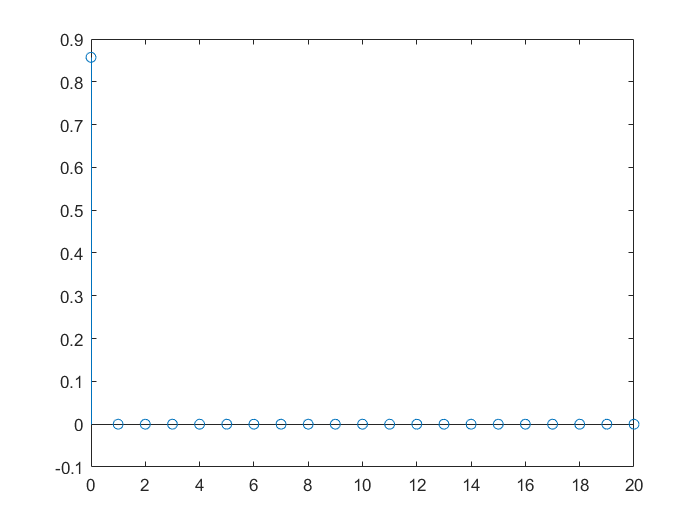

%comparo con el resultado teorico
xteor=delta(n,0)+0.7.^(n-1).*escalon(n,1);
stem(n,x-xteor)

%X2=(1+0.3*z^(-1))/(1-0.7*z^(-1)+0.49*z^(-2));
num2=[1,0.3];
denom2=[1,-0.7,0.49];
[r,p,k]=residuez(num2,denom2) %obtengo dos valores de r y dos de p con parte imaginaria, conjugados

r =    0.5000 - 0.5361i
   0.5000 + 0.5361i


p =    0.3500 + 0.6062i
   0.3500 - 0.6062i



k =

     []



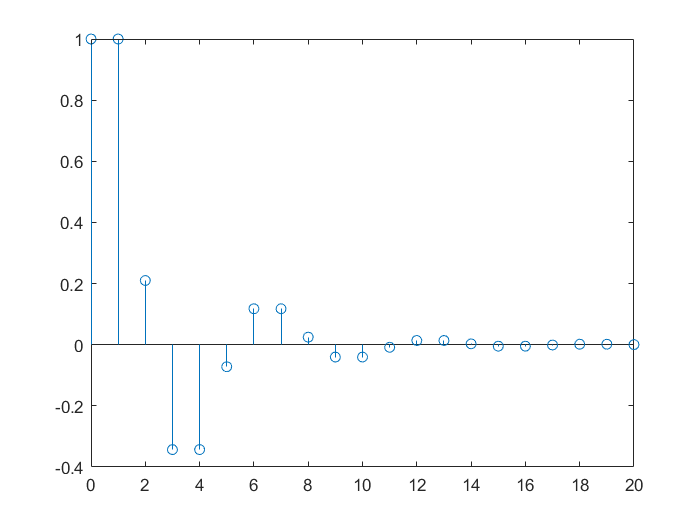

x2=r(1)*(p(1).^n).*escalon(n,0) + r(2)*(p(2).^n).*escalon(n,0);  %-k(1).*delta(n,0) en este caso no hay residuo porque no hay valor de k
%al sumar ambos polinomios, si representase la parte imaginar, esta se anularia ya que son conjugados
stem(n,real(x2)) %la parte real si que me da un valor

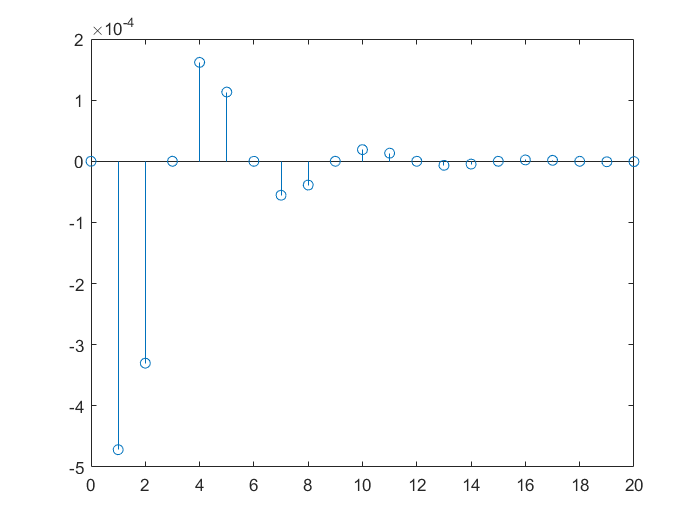

%comparo con lo teorico
x2teor=0.7.^n.*(1.073*sin((pi/3).*n)+cos((pi/3).*n)).*escalon(n,0);
stem(n,x2-x2teor)

%X3= (1-0,48*z^(-1)/(1-1,6z^(-1)+0,64*z^(-2))
num3=[1,-0.48];
denom3=[1,-1.6,0.64]

denom3 =     1.0000   -1.6000    0.6400


[r,p,k]=residuez(num3,denom3) %obtengo dos valores de r y dos de p sin parte imaginaria

r =    0.6000 + 0.0000i
   0.4000 - 0.0000i


p =    0.8000 + 0.0000i
   0.8000 - 0.0000i



k =

     []



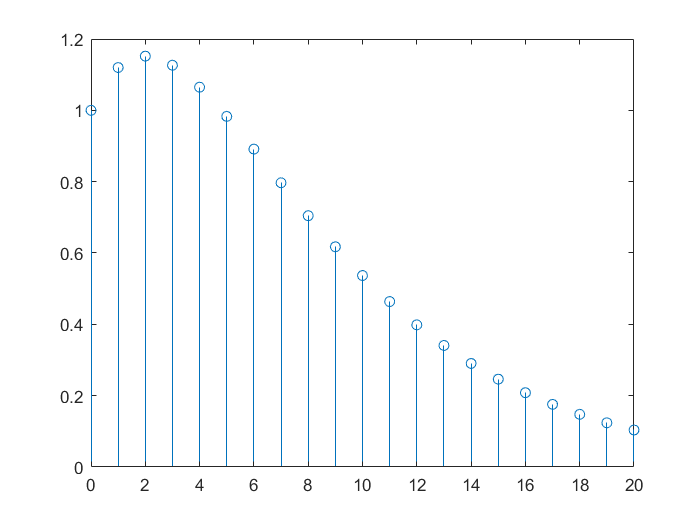

%dado que hay dos polos en el mismo sitio, es un CASO ESPECIAL
x3_1=r(1)*(p(1).^n).*escalon(n,0); %tampoco hay residuo
x3_2=(r(2)/p(2)).*(n+1).*(p(2).^(n+1)).*escalon(n,-1);
x3=(x3_1)+(x3_2);
stem(n,real(x3))

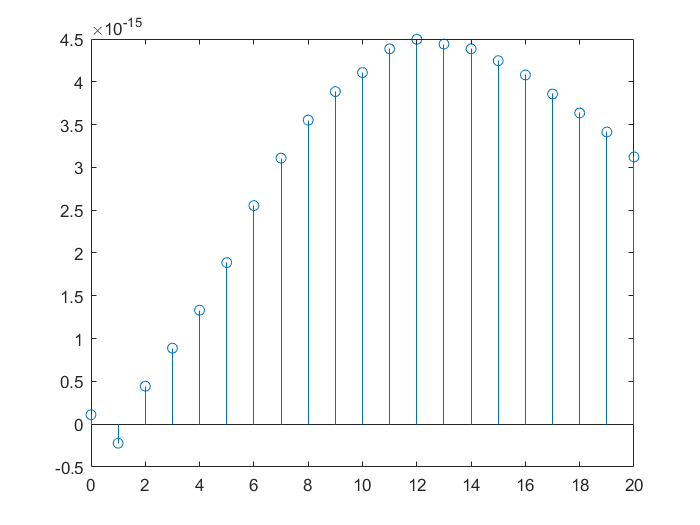

%tem(n,imag(x3)) si quisiese representar la parte imaginaria, que no es nula
%comparo con lo teorico
x3teor=(1+0.4.*n).*(0.8.^n).*escalon(n,0);
stem(n,real(x3teor)-real(x3))